m = 3;
vv = 9;

N = 10 .^ (2:6);
gamma = 0.05;
T = 10000;
for n = N
    P1 = 0;
    P2 = 0;
    P3 = 0;

    for i = 1:T
        X = m + randn(1, n) * sqrt(vv);

        mint = confint_mean_any(X, 1 - gamma);
        mintn = confint_mean_norm(X, 1 - gamma);
        vint = confint_var_norm(X, 1 - gamma);

        P1 = P1 + (mint(1) < m && m < mint(2));
        P2 = P2 + (mintn(1) < m && m < mintn(2));
        P3 = P3 + (vint(1) < vv && vv < vint(2));
    end

    disp(n)

    disp(P1 / T)
    disp(P2 / T)
    disp(P3 / T)
end

   100



    0.9482



    0.9509



    0.9439



        1000



    0.9486



    0.9489



    0.9469



       10000



    0.9488



    0.9489



    0.9511



      100000



    0.9495



    0.9495



    0.9502



     1000000



    0.9531



    0.9531



    0.9519



x = [-5:.1:30];
y1 = chi2pdf(x, 10);
y3 = chi2cdf(x, 10);

chi2inv(0.025, 10)

ans = 3.2470

chi2inv(0.975, 10)

ans = 20.4832

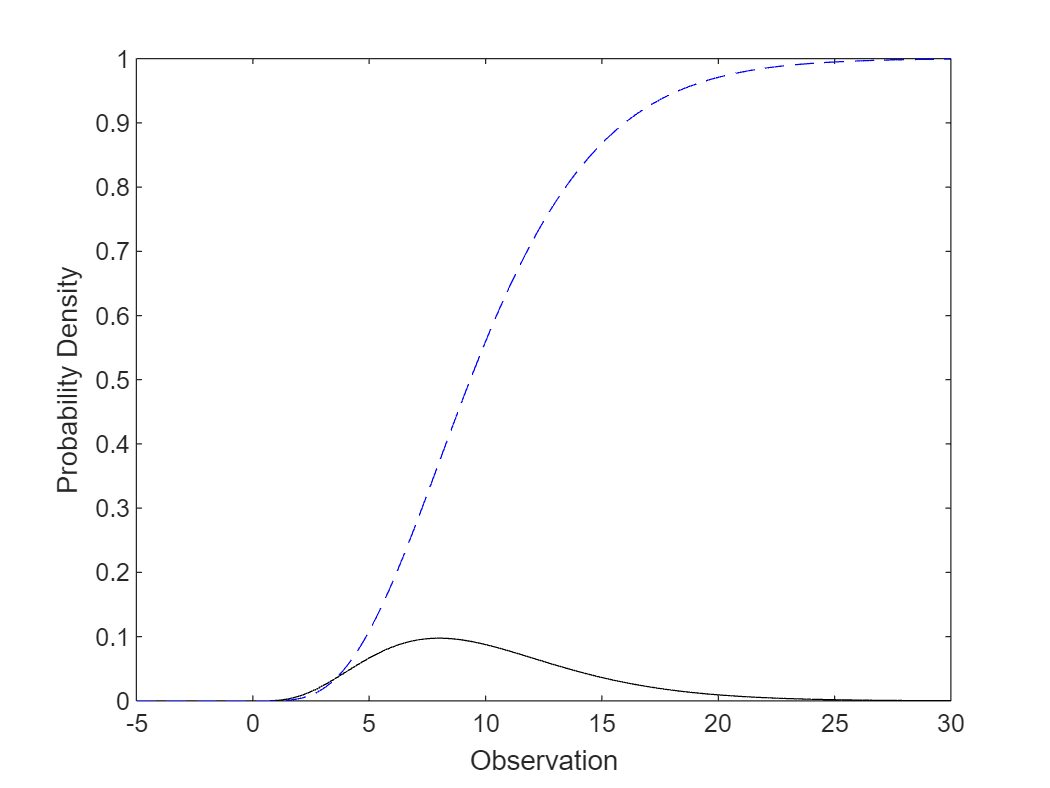


figure;
plot(x,y1,'Color','black','LineStyle','-')
hold on
plot(x,y3,'Color','blue','LineStyle','--')
xlabel('Observation')
ylabel('Probability Density')
hold off